**WHR for W6L32: EXHAUST GAS, JACKET WATER and RADIATED HEAT FROM BLOCK AND ACCESSORIES (Desalination, RC, ORC, TEGs)**

**0. INPUT DATA**

Diesel engine

Particular_data = inputdlg ({'Engine load (% MCR)','Fuel consumption (g/kW·h)','Exhaust temperature after turbocompressor (K)','Exhaust gas mass flow (kg/s)', ...
    'Jacket water temperature at engine outlet (K)','Jacket water pump pressure (bar)','Jacket water pump efficiency', ...
    'Heat dissipated by engine block, CAC and LOC (kJ/s)','Sea water temperature (K)','Sea water pump pressure (bar)'},'Diesel engine');
Load = str2double (Particular_data{1}); % ENGINE LOAD
FO_Consumption = str2double (Particular_data{2}); % ENGINE FO
Exh_in = str2double (Particular_data{3}); % ENGINE EXH
m_exh = str2double (Particular_data{4}); % ENGINE EXH
T_D2 = str2double (Particular_data{5}); % ENGINE JW
HT_pump = str2double (Particular_data{6}) * 100000; % JW PUMP
Pump_eff = str2double (Particular_data{7}); % JW PUMP
Heat_block = str2double (Particular_data{8}); % ENGINE BLOCK, CAC AND LOC
T_sw_in = str2double (Particular_data{9}); % SW PUMP
P_sw_in = (str2double (Particular_data{10})) * 100000; % SW PUMP
Power = 3000 * (Load/100); % ENGINE POWER

Waste Heat Recovery System

WHRS_data = inputdlg ({'RC Superheat (K)','RC Subcool (K)','ORC Superheat (K)','ORC Subcool (K)','ORC fluid pump pressure (bar)','ORC fluid pump efficiency', ...
    'Desalinator chamber absolute pressure (bar)','Desalinator pinch point (K)','Desalinator surface temperature (K)','Number of TEG modules installed','Temperature of TEG hot side (K)', ...
    'Temperature of TEG cold side (K)'},'WHRS');
RC_Superheat = str2double (WHRS_data{1}); % ENGINE JW
RC_Subcool = str2double (WHRS_data{2}); % ENGINE JW
ORC_Superheat = str2double (WHRS_data{3}); % ORC FLUID
ORC_Subcool = str2double (WHRS_data{4}); % ORC FLUID
ORC_Pump = str2double (WHRS_data{5}) * 100000; % ORC PUMP
ORC_Pump_eff = str2double (WHRS_data{6}); % ORC PUMP
P_chamber = (str2double (WHRS_data{7})) * 100000; % DESALINATION
Pinch_point_des = str2double (WHRS_data{8}); % DESALINATION
T_des_surface = str2double (WHRS_data{9}); % DESALINATION
N_TEG = str2double (WHRS_data{10}); % TEG
TEG_hot = str2double (WHRS_data{11}); % TEG hot side temperature
TEG_cold = str2double (WHRS_data{12}); % TEG cold side temperature

Hot source 1 - Exhaust gas

if (Exh_in <= 595)
    warndlg ({'Exhaust gas temperature introduced is too low.'},'Warning') % Exhaust gas temperature below W6L32 data at 30% MCR
end
if (Exh_in >= 750)
    warndlg ({'Exhaust gas temperature introduced is too high.'},'Warning') % Exhaust gas temperature above W6L32 data at 110% MCR
end
Exh_out = 413; % Desired exhaust gas temp outlet of RC Evaporator - OPERATIONAL CONDITION
Exh_min = 403.15; % Min temp to avoid cold corrosion, reference point, K - ACID DEW POINT LIMIT
if (m_exh <= 2)
    warndlg('Exhaust gas mass flow introduced is too low.','Warning') % Exhaust gas mass flow below engine data at 30% MCR
end
if (m_exh >= 7.5)
    warndlg('Exhaust gas mass flow introduced is too high.','Warning') % Exhaust gas mass flow over engine data at 110% MCR
end
Cp_exh = 1.185; % kJ/kg·K - KOSHY, 2015.

Hot source 2 - Jacket water

m_jw = 16.685; % kg/s - W6L32 data
Cp_jw = 4.05; % kJ/kg·K - Sample analysis
if (T_D2 <= 323.15)
    warndlg ({'Jacket Water temperature is too low.'},'Warning') % Minimum temperature of JW at the engine outlet: 50 ºC - ENGINE ALARM
end
if (T_D2 >= 388.15)
    warndlg ({'Jacket Water temperature is too high.'},'Warning') % Maximum temperature of JW at the engine outlet: 115 ºC - ENGINE ALARM (113 ºC)
end

Cold source - Sea water

m_sw = 11.62; % kg/s - OPERATIONAL CONDITION - FACET J100 and SW Pump ITUR Normabloc N2-40/160B/7.5-2900 rpm (40.8 m3/h at 2.4 bar)
if (T_sw_in <= 273.15)
    warndlg({'Sea water temperature introduced is too low.'},'Warning') % Sea water at 0ºC
end
if (T_sw_in >= 323.15)
    warndlg({'Sea water temperature introduced is too high.'},'Warning') % Sea water at 50ºC
end
if (P_sw_in <= 50000)
    warndlg({'Sea water pressure introduced is too low.'},'Warning') % Sea water at 0.5 bar
end
if (P_sw_in >= 500000)
    warndlg({'Sea water pressure introduced is too high.'},'Warning') % Sea water at 5 bar
end
Cp_sw = py.CoolProp.CoolProp.PropsSI('Cpmass','T',T_sw_in,'Q',0,"Water")/1000; % Cp Sea water, kJ/kg·K
Sw_density = 1025; % Sea water density, kg/m3 - STANDARD VALUE
Sw_pump_eff = 0.8;

Ambient conditions

T_env = 298.15; % K - ISO 15550:2002
Press_env = 100000; % Pa - ISO 15550:2002

TEG Limits

if (TEG_hot >= 473)
    warndlg ({'Thermoelectric modules cannot withstand temperatures over 200 ºC.'},'Warning') % Limit of Bi2Te3 TEG continuous operation
end
if (TEG_cold >= TEG_hot)
    warndlg ({'Thermoelectric modules temperatures are not consistent.'},'Warning')
end

**1. DESALINATION SYSTEM**

Operational desired conditions

Kjw = 25.6; % Constant for one phase evaporator
Des_area = 4.8; % Desalinator surface area, m2
Daily_cap = 22; % FW generation, m3/24h - MAX CAPACITY OF FW GENERATOR
T_D3 = 55 + 273.15; % JW outlet temperature from evaporator, K - OPERATIONAL CONDITION
PD2 = HT_pump; % JW inlet pressure to evaporator, Pa - OPERATIONAL CONDITION
PD3 = PD2 - 10000; % JW outlet pressure from evaporator, Pa
if (PD2 >= 500000)
    warndlg ({'Jacket Water pressure is too high for the desalination equipment.'},'Warning') % Maximum pressure of JW at the inlet of the desalinator: 5 bar, Pa
end
if (P_chamber < 9000)
    warndlg ({'Chamber press is too low.','The device cannot withstand this level of vacuumm.'},'Warning') % Minimum vacuum: 0,09 bar, Pa
end
if (P_chamber > 20000)
    warndlg ({'Chamber press is too high for desalination.'},'Warning') % Maximum chamber press: 0,2 bar, Pa
end
if (Pinch_point_des < 0)
    warndlg ({'Pinch point is too low for desalination'},'Warning') % Minimum pinch point: 0 K
end
if (Pinch_point_des > 30)
    warndlg ({'Pinch point is too high for desalination.'},'Warning') % Maximum pinch point: 30 K
end

Desalination process (Counterflow JW / SW)

T_des = py.CoolProp.CoolProp.PropsSI('T','Q',1,'P',P_chamber,"Water"); % Vaporization temperature of sea water inside desalination system, K
m_jw_des = (((Kjw*Daily_cap) / (T_D2 - T_D3)) * 1.025) / 3.6; % Mass flow needed on the evaporator, kg/s
m_jw_cycles = m_jw - m_jw_des; % mass flow remaining for the RC + ORC, kg/s
Q_jw_des = m_jw_des * Cp_jw * (T_D2 - T_D3); % Available heat from JW heat source, kJ/s
Q_radiation_des = (0.84 * 5.67 * 1e-8 * (T_des_surface)^4 * Des_area)/1000; % Heat radiated to environment (Emissivity * Stefan-Boltzmann constant * Desalinator temp * Des area), kJ
Q_sw_des = Q_jw_des - Q_radiation_des; % Available heat for fresh water generation, kJ/s
Q_sw_des_equivalent = Q_sw_des * (1 - (T_env / T_des)); % Equivalent amount of power, according to GUDE, 2009
H_D2 = (py.CoolProp.CoolProp.PropsSI('H','T',T_D2,'P',PD2,"Water"))/1000; % Enthalpy of jacket water at the inlet of the desalination, kJ/kg
S_D2 = (py.CoolProp.CoolProp.PropsSI('S','T',T_D2,'P',PD2,"Water"))/1000; % Entropy of jacket water at the inlet of the desalination, kJ/kg·K
H_D3 = (py.CoolProp.CoolProp.PropsSI('H','T',T_D3,'P',PD3,"Water"))/1000; % Enthalpy of jacket water at the outlet of the desalination, kJ/kg
S_D3 = (py.CoolProp.CoolProp.PropsSI('S','T',T_D3,'P',PD3,"Water"))/1000; % Enthalpy of jacket water at the outlet of the desalination, kJ/kg·K

**2. STEAM RANKINE CYCLE**

Operational desired conditions

if (RC_Superheat < 0)
    warndlg ({'Rankine Superheating is too low.'},'Warning') % Minimum superheating: 0 K
end
if (RC_Superheat > 25)
    warndlg ({'Rankine Superheating is too high.'},'Warning') % Maximum superheating: 25 K
end
if (RC_Subcool < 0)
    warndlg ({'Rankine Subcooling is too low.'},'Warning') % Minimum subcooling: 0 K
end
if (RC_Subcool > 25)
    warndlg ({'Rankine Subcooling is too high.'},'Warning') % Maximum subcooling: 25 K
end

Pump Conditions

if (Pump_eff <= 0)
    warndlg ({'Pump efficiency is too low.'},'Warning') 
end
if (Pump_eff > 1)
    warndlg ({'Pump efficiency is too high.'},'Warning')
end

Turbine Conditions

Turb_eff_RC = 0.8; % Turbine efficiency - OPERATIONAL CONDITION
Gen_eff_RC = 0.96; % Alternator efficiency - OPERATIONAL CONDITION

Condenser inside (Saturated liquid, RC1)

T_RC1 = (55 + 273.15) + RC_Subcool; % K
P_RC1 = py.CoolProp.CoolProp.PropsSI('P','T',T_RC1,'Q',0,"Water"); % Pa
S_RC1 = py.CoolProp.CoolProp.PropsSI('S','T',T_RC1,'Q',0,"Water")/1000; % kJ/kg·K

Condenser outlet (Subcooled liquid before engine, 1)

T_1 = 55 + 273.15; % Temperature of jacket water at the inlet of the engine, K - OPERATIONAL CONDITION
P_1 = P_RC1; % Pa
H_1 = py.CoolProp.CoolProp.PropsSI('H','T',T_1,'P',P_1,"Water")/1000; % kJ/kg
S_1 = py.CoolProp.CoolProp.PropsSI('S','T',T_1,'P',P_1,"Water")/1000; % kJ/kg·K
D_1 = py.CoolProp.CoolProp.PropsSI('D','T',T_1,'P',P_1,"Water"); % kg/m3
SpecVol_RC1 = 1/D_1; % m3/kg

Pump (Liquid pumped, 2s and 2)

P_2 = P_1 + HT_pump;  % Jacket water pump raises pressure, Pa
S_2s = S_1; % kJ/kg·K
w_spec_pump_ideal = (SpecVol_RC1 * (P_2 - P_1))/1000; % Specific work introduced on the pump, kJ/kg
H_2s = w_spec_pump_ideal + H_1; % Enthalpy at 2s, kJ/kg
W_pump_ideal = (m_jw * w_spec_pump_ideal); % Ideal work needed by the pump, kJ/s
W_pump_real = W_pump_ideal / Pump_eff; % Real work needed by the pump, kJ/s
H_2 = ((H_2s - H_1)/Pump_eff) + H_1; % Enthalpy at point 2, kJ/kg
H_2_joules = H_2 * 1000; % Enthalpy in J/kg for the correct calculation of T_2 and S_2
T_2 = py.CoolProp.CoolProp.PropsSI('T','P',P_2,'H',H_2_joules,"Water"); % Temperature of the jacket water at the outlet of the pump, K
S_2 = py.CoolProp.CoolProp.PropsSI('S','P',P_2,'H',H_2_joules,"Water")/1000; % Entropy of the jacket water at the outlet of the pump, kJ/kg·K
I_pump_RC = m_jw * T_env * (S_2 - S_1); % Irreversibilities on the pumping process, kJ/s

Engine (Liquid heated with pressure drop - First heat source, 2c)

T_2c = T_D2; % Temperature of jacket water at the outlet of the engine (W6L32 data), K
P_2c = P_2 - 55000; % Loss of pressure on engine, Pa - 0,55 bar - OPERATIONAL CONDITION
H_2c = py.CoolProp.CoolProp.PropsSI('H','T',T_2c,'P',P_2c,"Water")/1000; % kJ/kg
S_2c = py.CoolProp.CoolProp.PropsSI('S','T',T_2c,'P',P_2c,"Water")/1000; % kJ/kg·K
Q_engine = m_jw * Cp_jw * (T_2c - T_2); % Heat supplied to the cycle by the engine, kJ/s
I_engine = m_jw * T_env * (S_2c - S_2); % Irreversibilities due to engine heating and loss of pressure, kJ/s

Mass flow of jacket water used for RC and ORC

Q_exh = m_exh * Cp_exh * (Exh_in - Exh_out); % Heat available from exhaust gas, kJ/s
T_evap_RC = py.CoolProp.CoolProp.PropsSI('T','P',P_2c,'Q',0,"Water"); % Vaporization temperature of jacket water at P_2c, K
T_RC2 = T_D2; % Temperature of jacket water at the inlet of the evaporator, K
H_sat_vap_RC = py.CoolProp.CoolProp.PropsSI('H','P',P_2c,'Q',1,"Water")/1000; % Enthalpy of water saturated vapor at P_2c, kJ/kg
H_sat_liq_RC = py.CoolProp.CoolProp.PropsSI('H','P',P_2c,'Q',0,"Water")/1000; % Enthalpy of water saturated liquid at P_2c, kJ/kg
m_jw_RC = Q_exh / ((Cp_jw * (T_evap_RC - T_RC2)) + (H_sat_vap_RC - H_sat_liq_RC) + (Cp_jw * RC_Superheat) ); % Mass of jacket water for the RC (three steps method), kg/s
m_jw_ORC = m_jw_cycles - m_jw_RC; % Mass of jacket water available for ORC, kg/s 
I_engine_RC = m_jw_RC * T_env * (S_2c - S_2); % Irreversibilities due to engine heating and loss of pressure accounting for the RC, kJ/s

Evaporator (Counterflow Exh Gas / JW - Second heat source, RC2 and RC3)

H_RC2 = H_2c; % kJ/kg
S_RC2 = S_2c; % kJ/kg·K
T_RC3 = T_evap_RC + RC_Superheat; % Expected outlet temperature of jacket water at evaporator, K
P_RC3 = P_2c - 10000; % Loss of pressure in evaporator, Pa - OPERATIONAL CONDITION
H_RC3 = py.CoolProp.CoolProp.PropsSI('H','T',T_RC3,'P',P_RC3,"Water")/1000; % kJ/kg
S_RC3 = py.CoolProp.CoolProp.PropsSI('S','T',T_RC3,'P',P_RC3,"Water")/1000; % kJ/kg
T_avg_exh = (Exh_in - Exh_out) / log (Exh_in/Exh_out); % Exhaust average temperature inside the evaporator, K
I_evap_exh_RC = Q_exh * (1 - (T_env / T_avg_exh)); % Irreversibilities of the exhaust gas on evaporator, kJ/s
I_evap_jw_RC = m_jw_RC * (H_RC3 - H_RC2 - (T_env * (S_RC3 - S_RC2))); % Irreversibilities of the jacket water on evaporator, kJ/s
I_evap_RC_total = I_evap_exh_RC + I_evap_jw_RC; % Total irreversibilities on evaporator, kJ/s

Turbine (Expansion, 4s and 4)

P_RC4 = P_RC1 + 10000; % Loss of pressure in condenser, Pa - OPERATIONAL CONDITION
S_RC4s = S_RC3; % Isentropic process, kJ/kg·K
S_RC_P4_f = py.CoolProp.CoolProp.PropsSI('S','P',P_RC4,'Q',0,"Water")/1000; % kJ/kg·K
S_RC_P4_g = py.CoolProp.CoolProp.PropsSI('S','P',P_RC4,'Q',1,"Water")/1000; % kJ/kg·K
X_RC4s = (S_RC4s - S_RC_P4_f) / (S_RC_P4_g - S_RC_P4_f); % Steam quality at state 4s
H_RC_P4_f = py.CoolProp.CoolProp.PropsSI('H','P',P_RC4,'Q',0,"Water")/1000; % kJ/kg
H_RC_P4_g = py.CoolProp.CoolProp.PropsSI('H','P',P_RC4,'Q',1,"Water")/1000; % kJ/kg
H_RC4s = H_RC_P4_f + (X_RC4s * (H_RC_P4_g - H_RC_P4_f)); % kJ/kg
W_turbine_ideal_RC = (m_jw_RC * (H_RC3 - H_RC4s)); % Ideal work delivered by the turbine, kJ/s
H_RC4 = H_RC3 + (Turb_eff_RC * (H_RC4s - H_RC3)); % kJ/kg
H_RC4_joules = H_RC4 * 1000; % Enthalpy in J/kg for calculations
T_RC4 = py.CoolProp.CoolProp.PropsSI('T','P',P_RC4,'H',H_RC4_joules,"Water"); % K
S_RC4 = py.CoolProp.CoolProp.PropsSI('S','P',P_RC4,'H',H_RC4_joules,"Water")/1000; % kJ/kg·K
X_RC4 = (S_RC4 - S_RC_P4_f) / (S_RC_P4_g - S_RC_P4_f); % Steam quality at state 4
W_turbine_real_RC = W_turbine_ideal_RC * Turb_eff_RC; % Real work delivered by the turbine, kJ/s
Gen_power_RC = W_turbine_real_RC * Gen_eff_RC; % Electrical power delivered to the grid by the RC, kJ/s
I_turbine_RC = m_jw_RC * T_env * (S_RC4 - S_RC3); % Irreversibilities of turbine, kJ/s

Condenser (Counterflow JW / SW - Cool source, 4 and RC1)

T_cond_RC = py.CoolProp.CoolProp.PropsSI('T','P',P_RC4,'Q',1,"Water"); % Condensation temperature of jacket water at P_4, K
Q_cond_jw_RC = m_jw_RC * Cp_jw * (T_RC4 - T_1); % Heat to disipate into Sea Water in order to fully condense Jacket Water, kJ/s
Q_cond_RC = m_jw_RC * (H_RC4 - H_1); % Total heat on condenser, kJ/s

**3. ORC**

Operational desired conditions

if (ORC_Superheat < 0)
    warndlg ({'Organic Rankine Superheating is too low.'},'Warning') % Minimum superheating: 0 K
end
if (ORC_Superheat > 25)
    warndlg ({'Organic Rankine Superheating is too high.'},'Warning') % Maximum superheating: 25 K
end
if (ORC_Subcool < 0)
    warndlg ({'Organic Rankine Subcooling is too low.'},'Warning') % Minimum subcooling: 0 K
end
if (ORC_Subcool > 25)
    warndlg ({'Organic Rankine Subcooling is too high.'},'Warning') % Maximum subcooling: 25 K
end

Operation conditions

T_evap_jw_ORC_in = T_D2; % Jacket water temperature at the inlet of ORC evaporator, K
T_evap_jw_ORC_out = 55 + 273.15; % Jacket water temperature at the outlet of the ORC evaporator, K
T_cond_ORC = T_sw_in + 5; % Estimated temperature of condensation for the ORC, K - OPERATIONAL CONDITION
P_cond_ORC = py.CoolProp.CoolProp.PropsSI('P','T',T_cond_ORC,'Q',1,"Cyclohexane"); % Condensation pressure of ORC at the estimated T_cond_ORC, Pa
Cp_ORC = py.CoolProp.CoolProp.PropsSI('Cpmass','T',T_cond_ORC,'Q',0,"Cyclohexane")/1000; % Cp of ORC fluid, kJ/kg·K
Q_evap_jw_ORC = m_jw_ORC * Cp_jw * (T_evap_jw_ORC_in - T_evap_jw_ORC_out); % Available heat for ORC on jacket water, kJ/s

ORC Condenser outlet (Subcooled liquid before pump, 1)

T_ORC1 = T_cond_ORC - ORC_Subcool; % Temperature at state 1 of ORC, K
P_ORC1 = P_cond_ORC; % Pressure at state 1 of ORC, Pa
H_ORC1 = py.CoolProp.CoolProp.PropsSI('H','T',T_ORC1,'P',P_ORC1,"Cyclohexane")/1000; % kJ/kg
S_ORC1 = py.CoolProp.CoolProp.PropsSI('S','T',T_ORC1,'P',P_ORC1,"Cyclohexane")/1000; % kJ/kg·K
D_ORC1 = py.CoolProp.CoolProp.PropsSI('D','T',T_ORC1,'P',P_ORC1,"Cyclohexane"); % kg/m3
SpecVol_ORC1 = 1/D_ORC1; % m3/kg

ORC Pump (Liquid pumped, ORC2s and ORC2)

P_ORC2 = P_ORC1 + ORC_Pump; % Pa
S_ORC2s = S_ORC1; % kJ/kg
w_spec_pump_ORC_ideal = (SpecVol_ORC1 * (P_ORC2 - P_ORC1))/1000; % Specific work introduced on the ORC pump, kJ/kg
H_ORC2s = w_spec_pump_ORC_ideal + H_ORC1; % Enthalpy at state 2s of ORC, kJ/kg
H_ORC2 = ((H_ORC2s - H_ORC1)/ORC_Pump_eff) + H_ORC1; % Enthalpy at state 2 of ORC, kJ/kg
H_ORC2_joules = H_ORC2 * 1000; % Enthalpy in J/kg for the correct calculation of T_ORC2 and S_ORC2
T_ORC2 = py.CoolProp.CoolProp.PropsSI('T','P',P_ORC2,'H',H_ORC2_joules,"Cyclohexane"); % Temperature of the jacket water at the outlet of the pump, K
S_ORC2 = py.CoolProp.CoolProp.PropsSI('S','P',P_ORC2,'H',H_ORC2_joules,"Cyclohexane")/1000; % Entropy of the jacket water at the outlet of the pump, kJ/kg·K
T_evap_ORC = py.CoolProp.CoolProp.PropsSI('T','P',P_ORC2,'Q',0,"Cyclohexane"); % Vaporization temperature of ORC fluid, K
T_ORC3 = T_evap_ORC + ORC_Superheat; % Temperature of ORC fluid at the outlet of evaporator, K
T_crit = py.CoolProp.CoolProp.PropsSI('Tcrit',"Cyclohexane"); % Critical temperature of the ORC fluid
if (T_crit < T_ORC3)
    warndlg ({'Organic Rankine Cycle is on Supercritical state.'},'Warning')
end
P_ORC3 = P_ORC2 - 10000; % Drop of pressure inside ORC evaporator, Pa
H_ORC3 = py.CoolProp.CoolProp.PropsSI('H','T',T_ORC3,'P',P_ORC3,"Cyclohexane")/1000; % kJ/kg
m_ORC = Q_evap_jw_ORC / ((Cp_ORC * (T_evap_ORC - T_ORC2)) + (H_ORC3 - H_ORC2) + (Cp_ORC * ORC_Superheat)); % Mass flow of ORC fluid inside the circuit, kg/s
W_pump_ideal_ORC = (m_ORC * w_spec_pump_ORC_ideal); % Work ideally needed by the ORC pump, kJ/s
W_pump_real_ORC = W_pump_ideal_ORC / ORC_Pump_eff; % Work introduced on the ORC pump, kJ/s
I_pump_ORC = m_ORC * T_env * (S_ORC2 - S_ORC1); % Irreversibilities on the ORC pumping process, kJ/s

ORC Evaporator (Counterflow JW / ORC fluid, ORC3)

S_ORC3 = py.CoolProp.CoolProp.PropsSI('S','T',T_ORC3,'P',P_ORC3,"Cyclohexane")/1000; % kJ/kg·K
T_avg_ORC = (T_evap_jw_ORC_in - T_evap_jw_ORC_out) / log (T_evap_jw_ORC_in / T_evap_jw_ORC_out); % Exhaust average temperature inside the evaporator, K
I_evap_jw_ORC = Q_evap_jw_ORC * (1 - (T_env / T_avg_ORC)); % Irreversibilities of the jacket water on ORC evaporator, kJ/s
I_evap_ORC = m_ORC * (H_ORC3 - H_ORC2 - (T_env * (S_ORC3 - S_ORC2))); % Irreversibilities of the ORC fluid on ORC evaporator, kJ/s
I_evap_ORC_total = I_evap_jw_ORC + I_evap_ORC; % Total irreversibilities on ORC evaporator, kJ/s

ORC Turbine (Expansion, ORC4)

Turb_eff_ORC = 0.8; % ORC Turbine efficiency - OPERATIONAL CONDITION
Gen_eff_ORC = 0.96; % ORC Generator efficiency - OPERATIONAL CONDITION
P_ORC4 = P_ORC1 + 10000; % Loss of pressure in condenser, Pa - OPERATIONAL CONDITION
S_ORC4s = S_ORC3; % Isentropic process, kJ/kg·K
S_P4_f_ORC = py.CoolProp.CoolProp.PropsSI('S','P',P_ORC4,'Q',0,"Cyclohexane")/1000; % kJ/kg·K
S_P4_g_ORC = py.CoolProp.CoolProp.PropsSI('S','P',P_ORC4,'Q',1,"Cyclohexane")/1000; % kJ/kg·K
X_ORC4s = (S_ORC4s - S_P4_f_ORC) / (S_P4_g_ORC - S_P4_f_ORC); % Steam quality at state 4s
S_ORC4s_joules = S_ORC3 * 1000; % Entropy in J/kg·K for calculations
H_P4_f_ORC = py.CoolProp.CoolProp.PropsSI('H','P',P_ORC4,'Q',0,"Cyclohexane")/1000; % kJ/kg
H_P4_g_ORC = py.CoolProp.CoolProp.PropsSI('H','P',P_ORC4,'Q',1,"Cyclohexane")/1000; % kJ/kg
H_ORC4s = H_P4_f_ORC + (X_ORC4s * (H_P4_g_ORC - H_P4_f_ORC)); % kJ/kg
W_turbine_ideal_ORC = (m_ORC * (H_ORC3 - H_ORC4s)); % Ideal work delivered by ORC turbine, kJ/s
H_ORC4 = H_ORC3 + (Turb_eff_ORC * (H_ORC4s - H_ORC3))/1000; % kJ/kg
H_ORC4_joules = H_ORC4 * 1000; % Enthalpy in J/kg for calculations
T_ORC4 = py.CoolProp.CoolProp.PropsSI('T','P',P_ORC4,'H',H_ORC4_joules,"Cyclohexane"); % K
S_ORC4 = py.CoolProp.CoolProp.PropsSI('S','P',P_ORC4,'H',H_ORC4_joules,"Cyclohexane")/1000; % kJ/kg·K
X_ORC4 = (S_ORC4 - S_P4_f_ORC) / (S_P4_g_ORC - S_P4_f_ORC); % Steam quality at state 4
W_turbine_real_ORC = W_turbine_ideal_ORC * Turb_eff_ORC; % Real work delivered by the ORC turbine, kJ/s
Gen_power_ORC = W_turbine_real_ORC * Gen_eff_ORC; % Electrical power delivered to the grid by the ORC, kJ/s
I_turbine_ORC = m_ORC * T_env * (S_ORC4 - S_ORC3); % Irreversibilities on the turbine, kJ/s

ORC Condenser (Liquid, ORC1)

H_sat_vap_ORC = py.CoolProp.CoolProp.PropsSI('H','P',P_ORC4,'Q',1,"Cyclohexane")/1000; % Enthalpy of ORC saturated vapor at P_2c, kJ/kg
H_sat_liq_ORC = py.CoolProp.CoolProp.PropsSI('H','P',P_ORC4,'Q',0,"Cyclohexane")/1000; % Enthalpy of ORC saturated liquid at P_2c, kJ/kg
Q_cond_ORC = m_ORC * ((Cp_ORC * (T_ORC4 - T_cond_ORC)) + (H_sat_vap_ORC - H_sat_liq_ORC) + (Cp_ORC * ORC_Subcool)); % Total heat on condenser, kJ/s

**4. THERMOELECTRIC GENERATORS**

A_TEG = 0.0016; % Area of a 40x40 mm TEG module, m2
A_engine = 35.81; % Area of engine block + CAC + LOC, m2
Occup_factor = ((N_TEG * A_TEG) / A_engine) * 100; % Occupancy ratio of the TEG module inside the engine
if (Occup_factor > 100)
    warndlg ({'TEGs installed exceed the engine area.'},'Warning') 
end
Q_TEG = Heat_block * (Occup_factor / 100); % Percentage of heat block, CAC and LOC used on the TEGs, kJ/s
TEG_gradient = TEG_hot - TEG_cold; % Temperature gradient of TEG between faces, K
if (TEG_gradient <= 60)
   TEG_output = 0.901 * N_TEG; % Amount of energy recovered, Watts
elseif (61 <= TEG_gradient)
   TEG_output = 3.299 * N_TEG; % Amount of energy recovered, Watts 
end
if (121 <= TEG_gradient)
   TEG_output = 6.299 * N_TEG; % Amount of energy recovered, Watts 
end
TEG_output_kW = TEG_output / 1000; % kW

**5. SEA WATER CONDITIONS**

H_sw_in = py.CoolProp.CoolProp.PropsSI('H','P',P_sw_in,'T',T_sw_in,"Water")/1000; % Enthalpy of sea water at the inlet of the condenser, kJ/kg
S_sw_in = py.CoolProp.CoolProp.PropsSI('S','P',P_sw_in,'T',T_sw_in,"Water")/1000; % Entropy of sea water at the inlet of the condenser, kJ/kg
T_sw_out_ORC_1 = T_sw_in + (Q_cond_ORC / (m_sw * Cp_sw)); % Sea water temperature at the outlet of ORC condenser, K
P_sw_out_ORC_1 = P_sw_in - 10000; % Loss of pressure on ORC condenser, Pa
H_sw_out_ORC = py.CoolProp.CoolProp.PropsSI('H','P',P_sw_out_ORC_1,'T',T_sw_out_ORC_1,"Water")/1000; % Enthalpy of sea water at the outlet of ORC condenser, kJ/kg
S_sw_out_ORC = py.CoolProp.CoolProp.PropsSI('S','P',P_sw_out_ORC_1,'T',T_sw_out_ORC_1,"Water")/1000; % Entropy of sea water at the outlet of ORC condenser, kJ/kg·K
T_sw_in_RC_2 = T_sw_out_ORC_1;
P_sw_in_RC_2 = P_sw_out_ORC_1;
H_sw_in_RC = py.CoolProp.CoolProp.PropsSI('H','P',P_sw_in_RC_2,'T',T_sw_in_RC_2,"Water")/1000; % Enthalpy of sea water at the inlet of RC condenser, kJ/kg
S_sw_in_RC = py.CoolProp.CoolProp.PropsSI('S','P',P_sw_in_RC_2,'T',T_sw_in_RC_2,"Water")/1000; % Entropy of sea water at the inlet of RC condenser, kJ/kg·K
T_sw_out_RC_2 = T_sw_in_RC_2 + (Q_cond_jw_RC / (m_sw * Cp_sw)); % Sea water temp at the outlet of the evaporator, K
P_sw_out_RC_2 = P_sw_in_RC_2 - 10000; % Loss of pressure on RC condenser, Pa
H_sw_out_RC = py.CoolProp.CoolProp.PropsSI('H','P',P_sw_out_RC_2,'T',T_sw_out_RC_2,"Water")/1000; % Enthalpy of sea water at the outlet of RC condenser, kJ/kg
S_sw_out_RC = py.CoolProp.CoolProp.PropsSI('S','P',P_sw_out_RC_2,'T',T_sw_out_RC_2,"Water")/1000; % Entropy of sea water at the outlet of RC condenser, kJ/kg·K
T_sw_in_DES_3 = T_sw_out_RC_2;
P_sw_in_DES_3 = P_sw_out_RC_2;
H_sw_in_DES_3 = py.CoolProp.CoolProp.PropsSI('H','P',P_sw_in_DES_3,'T',T_sw_in_DES_3,"Water")/1000; % Enthalpy of sea water at the inlet of the desalination, kJ/kg
S_sw_in_DES_3 = py.CoolProp.CoolProp.PropsSI('S','P',P_sw_in_DES_3,'T',T_sw_in_DES_3,"Water")/1000; % Entropy of sea water at the inlet of the desalination, kJ/kg·K
P_sw_out_DES_3 = P_sw_in_DES_3 - 10000; % Loss of pressure on desalination condenser, Pa
T_sw_out_DES_3 = T_sw_in_DES_3; % Sea water general outlet from desalination, K - ASSUMED ALL HEAT GOES INTO EVAPORATION
T_sw_out_DES_3_distillate = T_D2 - Pinch_point_des; % Sea water outlet temperature according to Pinch Point, K
if (T_des >= T_sw_out_DES_3_distillate)
    warndlg ({'The vaporization temperature of the desalination process is higher than the pinch point selected.'},'Error')
end
H_sw_out_DES_3 = py.CoolProp.CoolProp.PropsSI('H','P',P_sw_out_DES_3,'T',T_sw_out_DES_3,"Water")/1000; % Enthalpy of sea water at the outlet of the desalination, kJ/kg
S_sw_out_DES_3 = py.CoolProp.CoolProp.PropsSI('S','P',P_sw_out_DES_3,'T',T_sw_out_DES_3,"Water")/1000; % Entropy of sea water at the outlet of the desalination, kJ/kg·K
H_sw_DES_3_f = (py.CoolProp.CoolProp.PropsSI('H','P',P_chamber,'Q',0,"Water"))/1000; % kJ/kg
H_sw_DES_3_g = (py.CoolProp.CoolProp.PropsSI('H','P',P_chamber,'Q',1,"Water"))/1000; % kJ/kg
m_sw_distillate = Q_sw_des / ((Cp_sw * (T_des - T_sw_in_DES_3)) + (H_sw_DES_3_g - H_sw_DES_3_f) + (Cp_sw * (T_sw_out_DES_3_distillate - T_des))); % Mass flow of distillate, kg/s
m_sw_distillate_hour = m_sw_distillate * 3600; % Mass flow of distillate, kg/s
m_sw_out_DES_3 = m_sw - m_sw_distillate; % Not vaporized sea water, kg/s
T_sw_in_TEG_4 = T_sw_out_DES_3;
T_sw_out_TEG_4 = T_sw_in_TEG_4 + (Q_TEG / (m_sw_out_DES_3 * Cp_sw)); % Cooling of TEG with the remaining sea water on system
P_sw_in_TEG_4 = P_sw_out_DES_3;
P_sw_out_TEG_4 = P_sw_in_TEG_4 - 10000; % Loss of pressure on TEG cooler, Pa
if (T_sw_out_TEG_4 >= 333.15)
    warndlg ({'Sea water is exiting the WHRS at a temperature over 60 ºC.'},'Error')
end
if (P_sw_out_TEG_4 <= 100000)
    warndlg ({'Sea water is exiting the WHRS at a pressure lower than 1 bar.'},'Error')
end

RC Condenser

I_cond_jw = m_jw_RC *(H_RC4 - H_1 - (T_env * (S_RC4 - S_1))); % Irreversibilities of the jacket water on condenser, kJ/s
I_cond_sw_RC = m_sw * (H_sw_out_RC - H_sw_in_RC - (T_env * (S_sw_out_RC - S_sw_in_RC))); % Irreversibilities of the sea water on condenser, kJ/s
I_cond_RC_total = I_cond_jw + I_cond_sw_RC; % Total irreversibilities on the condenser, kJ/s

ORC Condenser

I_cond_ORC = m_ORC *(H_ORC1 - H_ORC4 - (T_env * (S_ORC1 - S_ORC4))); % Irreversibilities of the ORC fluid on condenser, kJ/s
I_cond_sw_ORC = m_sw * (H_sw_in - H_sw_out_ORC - (T_env * (S_sw_in - S_sw_out_ORC))); % Irreversibilities of the sea water on condenser, kJ/s
I_cond_ORC_total = I_cond_ORC + I_cond_sw_ORC; % Total irreversibilities on the condenser, kJ/s

Desalination

W_des_pump = 10.4; % Real work from the pump of the desalination system and ejector, kJ/s - ITUR Normabloc N2-40/160B/7.5-2900 rpm (40.8 m3/h at 2.4 bar)
Daily_distillate = (m_sw_distillate * 3600 * 24 ) / Sw_density; % Daily fresh water production, m3

**6. WHRS PERFORMANCE**

Rankine cycle performance

Heat_input_RC = (Q_engine * (m_jw_RC / m_jw)) + Q_exh; % Heat available from hot current, kJ/s
Cycle_output_RC = W_turbine_real_RC - W_pump_real; % Total work on the cycle, kJ/s
Cycle_output_gen_RC = Gen_power_RC - W_pump_real; % Total work recovered, kJ/s
Cycle_eff_RC = (Cycle_output_gen_RC / Heat_input_RC) * 100; % Real efficiency of the cycle (Electrical power vs. Exh gas heat)
Irreversibilities_RC = I_pump_RC + I_engine_RC + I_evap_RC_total + I_turbine_RC + I_cond_RC_total; % Total irreversibilities of the cycle, kJ/s
Exergy_eff_RC = (Cycle_output_gen_RC / (Cycle_output_gen_RC + Irreversibilities_RC))*100; % Exergy efficiency of the RC cycle

ORC performance

Heat_input_ORC = Q_evap_jw_ORC; % Heat available from hot current, kJ/s
Cycle_output_ORC = W_turbine_real_ORC - W_pump_real_ORC; % Total work on the cycle, kJ/s
Cycle_output_gen_ORC = Gen_power_ORC - W_pump_real_ORC; % Total work recovered, kJ/s
Cycle_eff_ORC = (Cycle_output_gen_ORC / Heat_input_ORC) * 100; % Real efficiency of the cycle (Electrical power vs. Jacket water heat)
Irreversibilities_ORC = I_pump_ORC + I_evap_ORC_total + I_turbine_ORC + I_cond_ORC_total; % Total irreversibilities of the cycle, kJ/s
Exergy_eff_ORC = (Cycle_output_gen_ORC / (Cycle_output_gen_ORC + Irreversibilities_ORC))*100; % Exergy efficiency of the ORC cycle

TEG performance

TEG_eff = (TEG_output_kW / Q_TEG) * 100; % Efficiency of the TEG
T_avg_TEG = (TEG_hot - TEG_cold) / log (TEG_hot / TEG_cold); % Average temperature inside the TEGs, K
I_TEG = Q_TEG * (1 - (T_env / T_avg_TEG)); % Irreversibilities on the TEG, kJ/s
Exergy_eff_TEG = (TEG_output_kW / (TEG_output_kW + I_TEG))*100; % Exergy efficiency of TEG system

Desalination performance

Desalination_eff = (Q_sw_des_equivalent / (Q_jw_des + W_des_pump))*100; % Efficiency of the desalination process
T_avg_des = (T_D2 - T_D3) / log (T_D2 / T_D3); % Average temperature of jacket water inside desalination system, K
I_des_jw = Q_jw_des * (1 - (T_env / T_avg_des)); % Irreversibilities of jacket water, kJ/s
I_des_sw = m_sw * (H_sw_in_DES_3 - H_sw_out_DES_3 - (T_env * (S_sw_in_DES_3 - S_sw_out_DES_3))); % Irreversibilities of sea water, kJ/s
I_des = I_des_jw + I_des_sw; % Total irreversibilities on desalination process, kJ/s
Exergy_eff_DES = (Q_sw_des_equivalent / (Q_jw_des + I_des))*100; % Exergy efficiency of desalination system

Entire WHRS performance

WHRS_heat_input = Heat_input_RC + Heat_input_ORC + Q_TEG + Q_jw_des; % Total heat input for WHRS, kJ/s
WHRS_cycle_output = Cycle_output_gen_RC + Cycle_output_gen_ORC + TEG_output_kW + Q_sw_des_equivalent; % Total output of WHRS, kJ/s
WHRS_eff = (WHRS_cycle_output / WHRS_heat_input)*100; % Thermal efficiency of WHRS
I_WHRS = Irreversibilities_RC + Irreversibilities_ORC + I_TEG + I_des; % Irreversibilities of WHRS, kJ/s
Exergy_eff_WHRS = (WHRS_cycle_output / (WHRS_cycle_output + I_WHRS))*100; % Exergy efficiency of WHRS

**7. FUEL SAVINGS**

Fuel_savings_RC = FO_Consumption * Cycle_output_gen_RC; % Fuel saved due to RC, g/h
Fuel_savings_ORC = FO_Consumption * Cycle_output_gen_ORC; % Fuel saved due to ORC, g/h
Fuel_savings_TEG = FO_Consumption * TEG_output_kW; % Fuel saved due to TEGs, g/h
Fuel_savings_DES = FO_Consumption * Q_sw_des_equivalent; % Fuel used on desalination, g/h
Fuel_savings_WHRS = Fuel_savings_RC + Fuel_savings_ORC + Fuel_savings_TEG + Fuel_savings_DES; % Total FO savings with the whole WHRS, g/h
Total_output = Power + Cycle_output_gen_RC + Cycle_output_gen_ORC + TEG_output_kW + Q_sw_des_equivalent; % Total power output with WHRS, kJ/s
New_FO = (Power * FO_Consumption) / Total_output; % New FO consumption with WHRS, g/kW·h
Fuel_savings_perc = 100 - ((New_FO / FO_Consumption) * 100); % Percentage of fuel saved with TEG installed

**8. RESULTS REPORT**

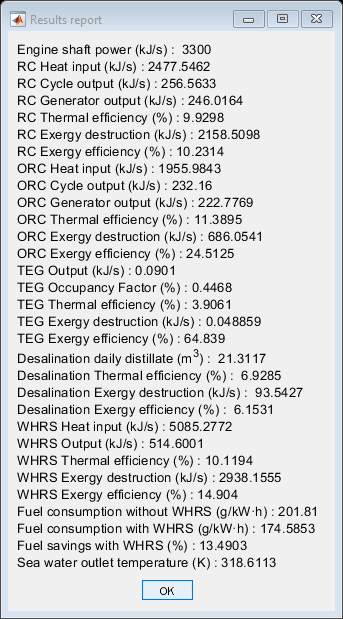

CreateStruct.Interpreter = 'tex';
CreateStruct.WindowStyle = 'modal';
Results = msgbox({['\fontsize{10}Engine shaft power (kJ/s) :  ',num2str(Power)]...
             ['RC Heat input (kJ/s) : ',num2str(Heat_input_RC)]...
             ['RC Cycle output (kJ/s) : ',num2str(Cycle_output_RC)]...
             ['RC Generator output (kJ/s) : ',num2str(Cycle_output_gen_RC)] ...
             ['RC Thermal efficiency (%) : ',num2str(Cycle_eff_RC)]...
             ['RC Exergy destruction (kJ/s) : ',num2str(Irreversibilities_RC)] ...
             ['RC Exergy efficiency (%) : ',num2str(Exergy_eff_RC)] ...
             ['ORC Heat input (kJ/s) : ',num2str(Heat_input_ORC)]...
             ['ORC Cycle output (kJ/s) : ',num2str(Cycle_output_ORC)]...
             ['ORC Generator output (kJ/s) : ',num2str(Cycle_output_gen_ORC)] ...
             ['ORC Thermal efficiency (%) : ',num2str(Cycle_eff_ORC)]...
             ['ORC Exergy destruction (kJ/s) : ',num2str(Irreversibilities_ORC)] ...
             ['ORC Exergy efficiency (%) : ',num2str(Exergy_eff_ORC)] ...
             ['TEG Output (kJ/s) : ',num2str(TEG_output_kW)] ...
             ['TEG Occupancy Factor (%) : ',num2str(Occup_factor)] ...
             ['TEG Thermal efficiency (%) : ',num2str(TEG_eff)] ...
             ['TEG Exergy destruction (kJ/s) : ',num2str(I_TEG)] ...
             ['TEG Exergy efficiency (%) : ',num2str(Exergy_eff_TEG)] ...
             ['Desalination daily distillate (m^3) :  ',num2str(Daily_distillate)] ...
             ['Desalination Thermal efficiency (%) :  ',num2str(Desalination_eff)] ...
             ['Desalination Exergy destruction (kJ/s) :  ',num2str(I_des)] ...
             ['Desalination Exergy efficiency (%) :  ',num2str(Exergy_eff_DES)] ...
             ['WHRS Heat input (kJ/s) : ',num2str(WHRS_heat_input)] ...
             ['WHRS Output (kJ/s) : ',num2str(WHRS_cycle_output)] ...
             ['WHRS Thermal efficiency (%) : ',num2str(WHRS_eff)] ...
             ['WHRS Exergy destruction (kJ/s) : ',num2str(I_WHRS)] ...
             ['WHRS Exergy efficiency (%) : ',num2str(Exergy_eff_WHRS)] ...
             ['Fuel consumption without WHRS (g/kW·h) : ',num2str(FO_Consumption)] ...
             ['Fuel consumption with WHRS (g/kW·h) : ',num2str(New_FO)] ...
             ['Fuel savings with WHRS (%) : ',num2str(Fuel_savings_perc)] ...
             ['Sea water outlet temperature (K) : ',num2str(T_sw_out_TEG_4)] }, 'Results report',CreateStruct);
set(Results, 'position', [550 250 245 435]);

**9. RESULTS TO EXCEL --> REPASAR RESULTS_TABLE**

save('WHRS_results.mat'); % Storage of workspace with results in a *.mat file


Results_table = table (Load,FO_Consumption,Exh_in,m_exh,T_D2,HT_pump,Pump_eff,Heat_block,T_sw_in,P_sw_in,Power,RC_Superheat,RC_Subcool,ORC_Superheat,ORC_Subcool,ORC_Pump,ORC_Pump_eff,P_chamber,Pinch_point_des,T_des_surface,N_TEG,TEG_hot,TEG_cold,T_sw_in_TEG_4,Exergy_eff_WHRS,WHRS_cycle_output,New_FO);

writetable (Results_table,'WHRS_results.xlsx','sheet','WHRS Results','Range','A1'); % Worskspace into an Excel file